Numerical Solution of Initial-Value Problems

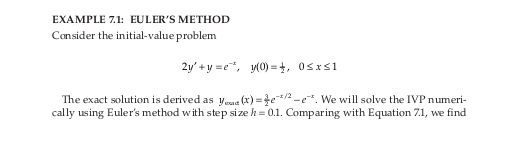

disp('  x   yEuler   yExact')

  x   yEuler   yExact


h = 0.1; x = 0:0.1:1; y0 = 1/2;
f = @(x,y)((exp(-x)-y)/2);
yEuler = EulerODE(f,x,y0);
% Solve the IVP
y_exact = dsolve('2*Dy + y = exp(-x)','y(0)=1/2','x');

% Convert for evaluation purposes
y_exact = matlabFunction(y_exact);

for k = 1:length(x),
    x_coord = x(k);
    yE = yEuler(k);
    yEx = y_exact(x(k));
    
    fprintf('%6.2f  %11.6f  %11.6f\n',x_coord,yE,yEx)
end

  0.00     0.500000     0.500000
  0.10     0.525000     0.522007
  0.20     0.543992     0.538525
  0.30     0.557729     0.550244
  0.40     0.566883     0.557776
  0.50     0.572055     0.561671
  0.60     0.573779     0.562416
  0.70     0.572531     0.560447
  0.80     0.568733     0.556151
  0.90     0.562763     0.549873
  1.00     0.554953     0.541917


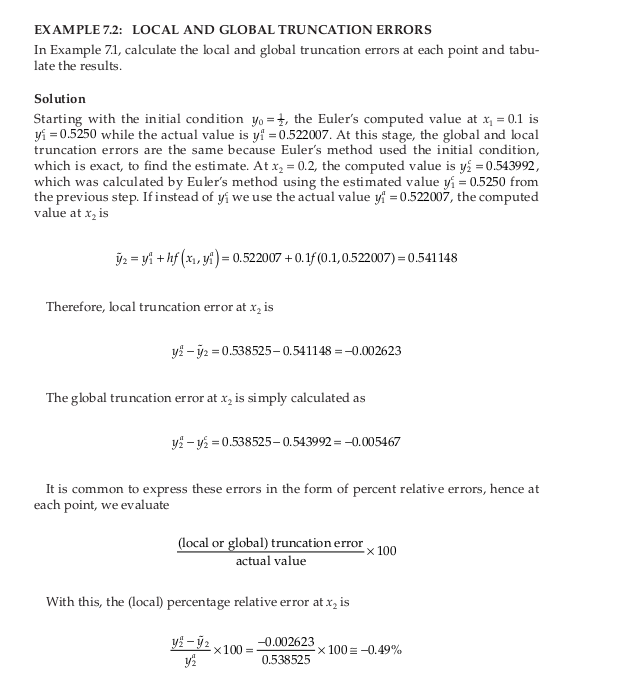

disp('  x   yEuler  yExact  e_local e_global')

  x   yEuler  yExact  e_local e_global


h = 0.1; x = 0:h:1; y0 = 1/2;
f = @(x,y)((exp(-x)-y)/2);
yEuler = EulerODE(f,x,y0);
y_exact = matlabFunction(dsolve('2*Dy + y = exp(-x)','y(0)=1/2','x'));


ytilda = 0*x; ytilda(1) = y0;
for n = 1:length(x)-1,
    ytilda(n+1) = y_exact(x(n)) + h*f(x(n),y_exact(x(n)));
end

for k = 1:length(x),
    x_coord = x(k);
    yE = yEuler(k);
    yEx = y_exact(x(k));
    e_local = (yEx-ytilda(k))/yEx*100;
    e_global = (yEx-yE)/yEx*100;

    fprintf('%6.2f  %11.6f   %11.6f %6.2f   %6.2f\n',x_coord,yE,yEx,e_local,e_global)
end

  0.00     0.500000      0.500000   0.00     0.00
  0.10     0.525000      0.522007  -0.57    -0.57
  0.20     0.543992      0.538525  -0.49    -1.02
  0.30     0.557729      0.550244  -0.42    -1.36
  0.40     0.566883      0.557776  -0.36    -1.63
  0.50     0.572055      0.561671  -0.31    -1.85
  0.60     0.573779      0.562416  -0.27    -2.02
  0.70     0.572531      0.560447  -0.23    -2.16
  0.80     0.568733      0.556151  -0.20    -2.26
  0.90     0.562763      0.549873  -0.17    -2.34
  1.00     0.554953      0.541917  -0.15    -2.41


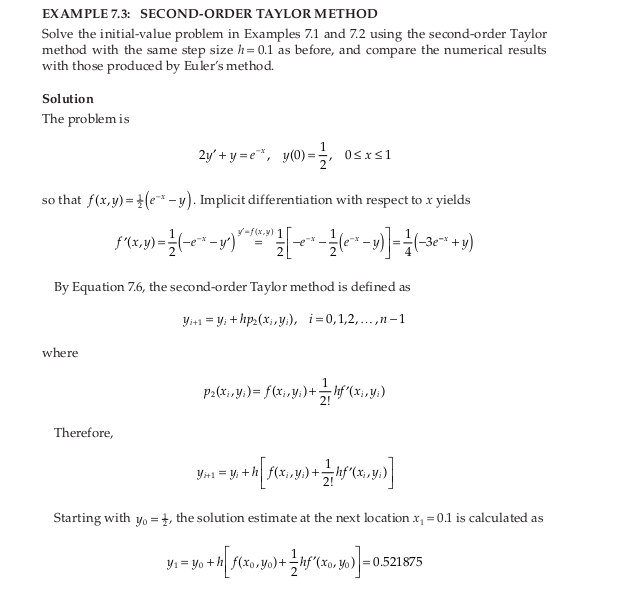

clc;clear;clf;
disp('  x   yEuler  yTaylor2    e_Euler e_Taylor2')

  x   yEuler  yTaylor2    e_Euler e_Taylor2


h = 0.1; x = 0:h:1; y0 = 1/2;
f = @(x,y)((exp(-x)-y)/2); fp = @(x,y)((-3*exp(-x)+y)/4);
yEuler = EulerODE(f,x,y0);
y_exact = matlabFunction(dsolve('2*Dy + y = exp(-x)','y(0)=1/2','x'));


yTaylor2 = 0*x; yTaylor2(1) = y0;
for i = 1:length(x)-1,
    yTaylor2(i+1) = yTaylor2(i)+h*(f(x(i),yTaylor2(i))+(1/2)*h*fp(x(i),yTaylor2(i)));
end

for k = 1:length(x),
    x_coord = x(k); yE = yEuler(k); yEx = y_exact(x(k)); yT = yTaylor2(k);
    e_Euler = (yEx-yE)/yEx*100;
    e_Taylor2 = (yEx-yT)/yEx*100;
    fprintf('%6.2f %11.6f %11.6f %6.2f %6.2f\n',x_coord,yE,yT,e_Euler,e_Taylor2)

end

  0.00    0.500000    0.500000   0.00   0.00
  0.10    0.525000    0.521875  -0.57   0.03
  0.20    0.543992    0.538282  -1.02   0.05
  0.30    0.557729    0.549907  -1.36   0.06
  0.40    0.566883    0.557362  -1.63   0.07
  0.50    0.572055    0.561193  -1.85   0.08
  0.60    0.573779    0.561887  -2.02   0.09
  0.70    0.572531    0.559878  -2.16   0.10
  0.80    0.568733    0.555551  -2.26   0.11
  0.90    0.562763    0.549249  -2.34   0.11
  1.00    0.554953    0.541277  -2.41   0.12


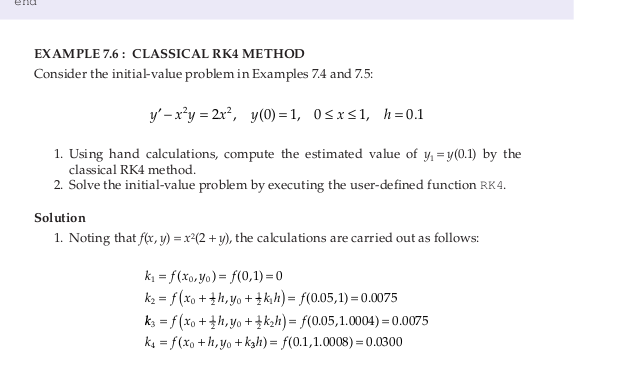

clear;clc;
f = @(x,y)((x^2)*(2+y));
x = 0:0.1:1;
y0 = 1;
y = RK4(f,x,y0); y = y'

y =    1.000000000000000
   1.001000156265625
   1.008010655265520
   1.027121833764230
   1.064687504397891
   1.127640660073439
   1.223965960120717
   1.363377214618958
   1.558285800173198
   1.825205587683566


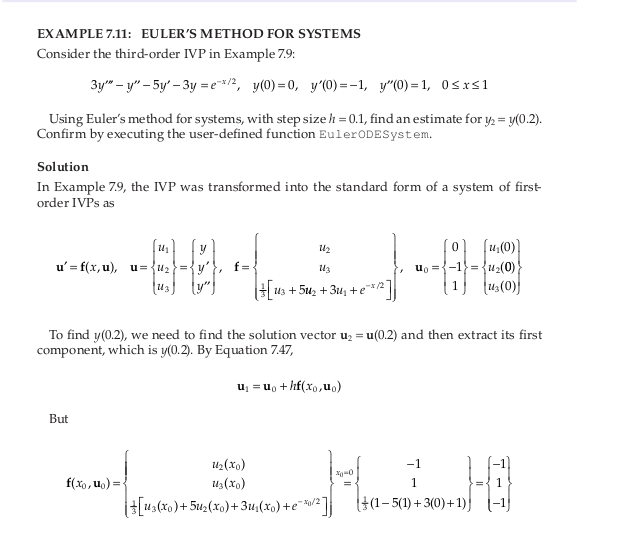

clear;clc;
f = @(x,u)([u(2);u(3);(u(3)+5*u(2)+3*u(1)+exp(-x/2))/3]);
x = 0:0.1:1;    % 11 mesh points
u0 = [0;-1;1];
u = EulerODESystem(f,x,u0); % Returns a 3-by-11 matrix

u(1,:)

ans =                    0  -0.100000000000000  -0.190000000000000  -0.271000000000000  -0.343982923525166  -0.409919922220326  -0.469776611324423  -0.524520336501841  -0.575128596767955  -0.622598775916443  -0.667959366554414


u(:,[2 3])

ans =   -0.100000000000000  -0.190000000000000
  -0.900000000000000  -0.810000000000000
   0.900000000000000   0.801707647483357


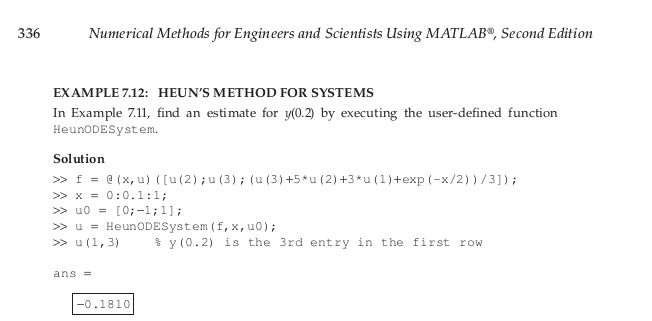

f = @(x,u)([u(2);u(3);(u(3)+5*u(2)+3*u(1)+exp(-x/2))/3]);
x = 0:0.1:1;
u0 = [0;-1;1];
u = HeunODESystem(f,x,u0);
u(1,3)  % y(0.2) is the 3rd entry in the first row

ans =   -0.180995730881292


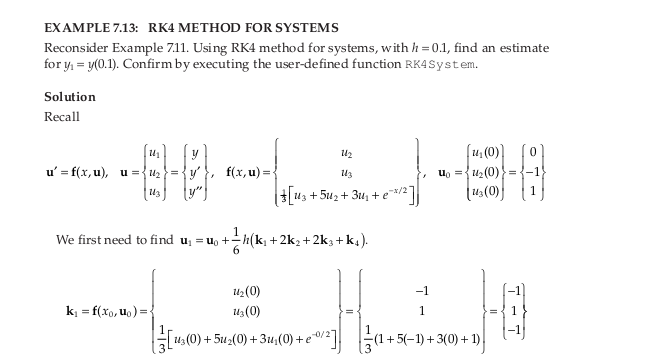

clear;clc;
f = @(x,u)([u(2);u(3);(u(3)+5*u(2)+3*u(1)+exp(-x/2))/3]);
x = 0:0.1:1;
u0 = [0;-1;1];
u = RK4System(f,x,u0);
u(1,2)  % y(0.1) is the 2nd entry in the first row

ans =   -0.095165963613555


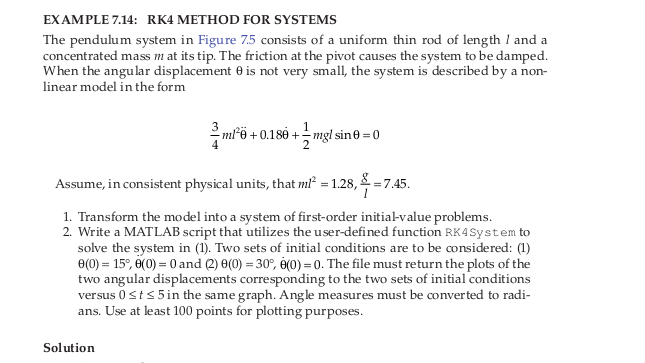

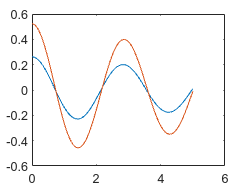

clear;clc;
t = linspace(0,5); u0 = [15*pi/180;0];
f = @(t,u)([u(2);-0.1875*u(2)-4.9667*sin(u(1))]);
uRK4 = RK4System(f,t,u0);
theta1 = uRK4(1,:); plot(t,theta1)
hold on
u0 = [30*pi/180;0];
uRK4 = RK4System(f,t,u0);
theta2 = uRK4(1,:); plot(t,theta2)

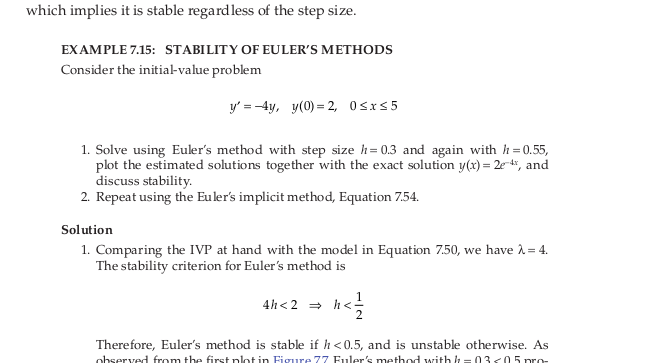

y0 = 2; f = @(x,y)(-4*y);
yExact = matlabFunction(dsolve('Dy+4*y=0','y(0)=2','x'));

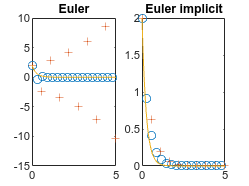

h1 = 0.3; x1 = 0:h1:5; h2 = 0.55; x2 = 0:h2:5;
% Euler's method with h = 0.3 and h = 0.55
y1 = EulerODE(f,x1,y0); y2 = EulerODE(f,x2,y0);

y1I(1) = y0;
for i = 2:length(x1),
    y1I(i) = y1I(i-1)/(1+4*h1);
end
y2I(1) = y0;
for i = 2:length(x2),
    y2I(i) = y2I(i-1)/(1+4*h2);
end

x3 = linspace(0,5);
ye = zeros(100,1);
for i = 1:100,
    ye(i) = yExact(x3(i));
end
subplot (1,2,1), plot(x1,y1,'o',x2,y2,'+',x3,ye,'-')
% Figure 7.7
title('Euler')
subplot (1,2,2), plot(x1,y1I,'o',x2,y2I,'+',x3,ye,'-')
title('Euler implicit')

buit-in function

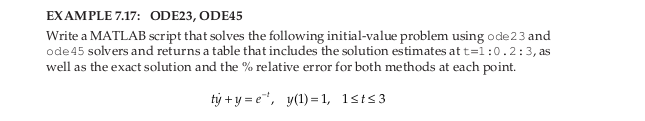

disp('  t   yode23  yode45  yExact  e_23    e_45')

  t   yode23  yode45  yExact  e_23    e_45


t = 1:0.2:3; y0 = 1;
f = @(t,y)((exp(-t)-y)/t);
[t,y23] = ode23(f,t,y0);
[t,y45] = ode45(f,t,y0);

yExact = matlabFunction(dsolve('t*Dy+y=exp(-t)','y(1)=1'));


for k=1:length(t),
    t_coord = t(k);
    yode23 = y23(k);
    yode45 = y45(k);
    yEx = yExact(t(k));
    e_23 = (yEx - yode23)/yEx*100;
    e_45 = (yEx - yode45)/yEx*100;
    fprintf('%6.2f %11.6f%11.6f %11.6f %11.6f %11.8f\n',t_coord,yode23,yode45,yEx,e_23,e_45)
end

  1.00    1.000000   1.000000    1.000000    0.000000  0.00000000
  1.20    0.888872   0.888904    0.888904    0.003589 -0.00000000
  1.40    0.800866   0.800916    0.800916    0.006202 -0.00000001
  1.60    0.728684   0.728739    0.728739    0.007554 -0.00000001
  1.80    0.668045   0.668100    0.668100    0.008314 -0.00000001
  2.00    0.616218   0.616272    0.616272    0.008770 -0.00000001
  2.20    0.571347   0.571398    0.571398    0.009058 -0.00000001
  2.40    0.532101   0.532151    0.532151    0.009250 -0.00000001
  2.60    0.497494   0.497541    0.497541    0.009383 -0.00000001
  2.80    0.466766   0.466810    0.466810    0.009479 -0.00000001
  3.00    0.439323   0.439364    0.439364    0.009470 -0.00000001


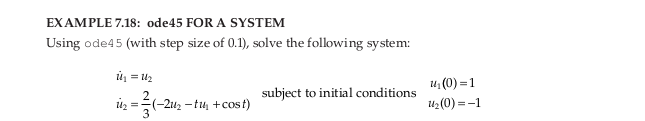

u0 = [1;-1]; t = 0:0.1:1;
f = @(t,u)([u(2);2*(-2*u(2)-t*u(1)+cos(t))/3]);
[t,u45] = ode45(f,t,u0)

t =                    0
   0.100000000000000
   0.200000000000000
   0.300000000000000
   0.400000000000000
   0.500000000000000
   0.600000000000000
   0.700000000000000
   0.800000000000000
   0.900000000000000


u45 =    1.000000000000000  -1.000000000000000
   0.909464873966093  -0.815857946371187
   0.835869473519323  -0.660513005368471
   0.776528315730713  -0.530209822193693
   0.729095485372509  -0.421885514095998
   0.691502950414409  -0.333023237790350
   0.661912167918806  -0.261531921388291
   0.638676611748947  -0.205647393874324
   0.620313277282648  -0.163851163535909
   0.605481551410500  -0.134803900329633


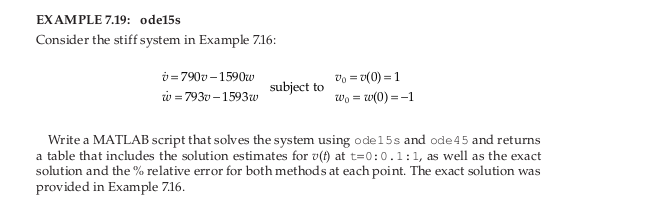

disp('  t   v15s    v45 vExact  e_15s   e_45')

  t   v15s    v45 vExact  e_15s   e_45



t = 0:0.1:1; u0 = [1;-1];
f = @(t,u)([790*u(1)-1590*u(2);793*u(1)-1593*u(2)]);

[t,u15s] = ode15s(f,t,u0);
% Values of v are in the first column of u15s

[t,u45] = ode45(f,t,u0);
% Values of v are in the first column of u45

uExact = @(t)([3180/797*exp(-3*t)-2383/797*exp(-800*t);1586/797*exp(-3*t)-2383/797*exp(-800*t)]);
for i = 1:length(t),
    uex(:,i) = uExact(t(i));    % Evaluate exact solution vector at each t
end

for k=1:length(t),
    t_coord = t(k);
    v15s = u15s(k,1); % Retain the first column of u15s: values of v
    v45 = u45(k,1); % Retain the first column of u45: values of v
    vExact = uex(1,k); % Retain the exact values of v

    e_15s = (vExact - v15s)/vExact*100;
    e_45 = (vExact - v45)/vExact*100;
    
    fprintf('%6.2f %11.6f %11.6f %11.6f %11.6f %11.8f \n',t_coord,v15s,v45,vExact,e_15s,e_45)

end

  0.00    1.000000    1.000000    1.000000    0.000000  0.00000000 
  0.10    2.955055    2.955511    2.955837    0.026464  0.01102274 
  0.20    2.187674    2.188567    2.189738    0.094262  0.05345813 
  0.30    1.620781    1.622657    1.622198    0.087342 -0.02830662 
  0.40    1.201627    1.201785    1.201754    0.010535 -0.00261497 
  0.50    0.890826    0.890278    0.890281   -0.061233  0.00033632 
  0.60    0.660191    0.659508    0.659536   -0.099254  0.00427387 
  0.70    0.489188    0.488525    0.488597   -0.121031  0.01461519 
  0.80    0.362521    0.361836    0.361961   -0.154754  0.03468108 
  0.90    0.268708    0.268171    0.268147   -0.209208 -0.00866986 
  1.00    0.199060    0.198645    0.198649   -0.207140  0.00178337 
